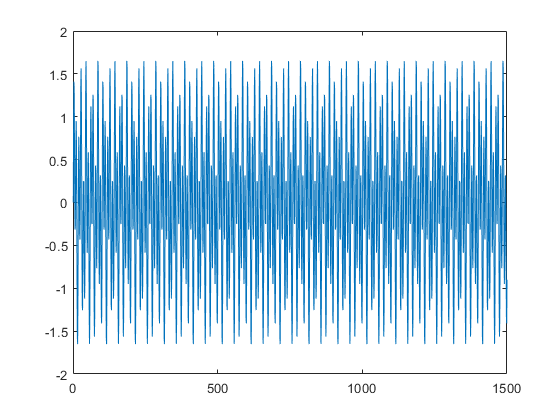

clear all
Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 1500;             % Length of signal
t = (0:L-1)*T;        % Time vector


S = 0.7*sin(2*pi*50*t) + sin(2*pi*120*t);

plot(S)

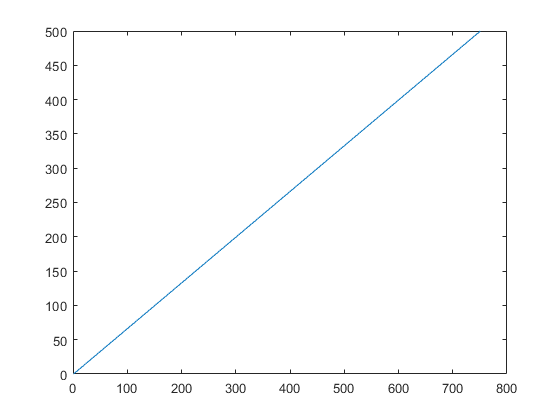


X = S + 2*randn(size(t));

Y = fft(X);

f = Fs*(0:(L/2))/L;

plot(f)

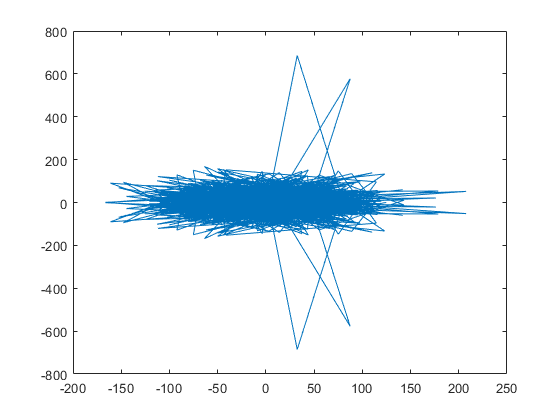

plot(Y)

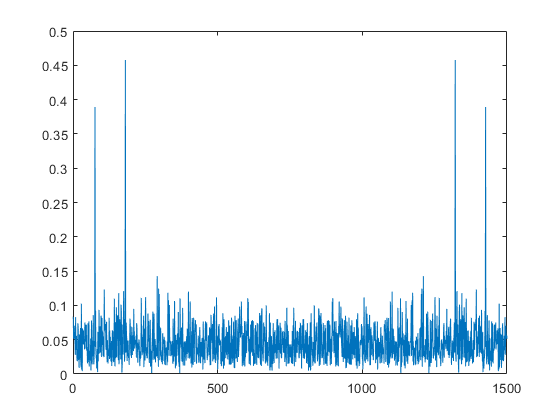


P2 = abs(Y/L);
P1 = P2(1:L/2+1);
% P1(2:end-1) = 2*P1(2:end-1);

plot(P2)

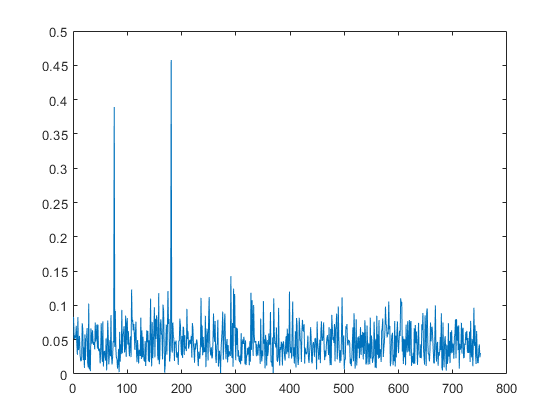

'arima' requires Econometrics Toolbox.

plot(P1)